# Computational Methods in Physics (PHY4605) - Loops

**Group Members**

- Name1 (MatricNumber1)

- Name2 (MatricNumber2)

**Instructions**: Work out the answers to all the following questions with your group members. Write your answers directly in this Live Script file and run any scripts/functions so that their outputs are shown. Then, save this file in the PDF format and name the file as: `LabXXShortName1Matric1ShortName2Matric2.pdf` (e.g., `Lab01Ahmad170637Abu170650.pdf`) before submitting. 

 1.  The following method of computing $\pi$ is due to Archimedes: 

     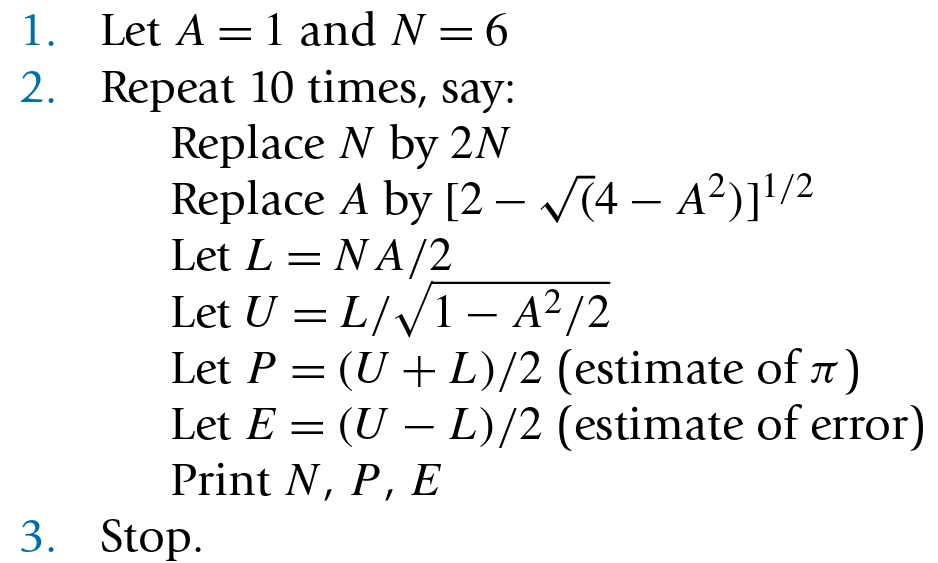

 Write a program to implement the algorithm.

**Answers:**

2. A square wave of period $T$ may be defined by the function:


$$f\left(t\right)=\left\lbrace \begin{array}{ll}
1 & \left(0<t<T\right)\\
-1 & \left(-T<t<0\right)
\end{array}\right.$$


 The Fourier series for $f\left(t\right)$ is given by:


$$F\left(t\right)=\frac{4}{\pi }\sum_{k=0}^{\infty } \frac{1}{2k+1}\sin \left\lbrack \frac{\left(2k+1\right)\pi t}{T}\right\rbrack$$
 

It is of interest to know how many terms are needed for a good approximation to this infinite sum. Taking $T=1$, write a program to compute and plot the sum to $n$ terms of the series for $t$ from $-1\ldotp 1$ to $1\ldotp 1$ in steps of $0\ldotp 01$, say. Run the program for $n=6$ and plot $F\left(t\right)$ against $t$. Then, change $n$ to a significantly bigger value, say $n=50$ and compare the plots produced.

**Answers:**

t = -1.1 : 0.01 : 1.1;
n = 6
T = 1;
F = 0;
for k = 0 : n
    F = F + (1 / (2*k + 1)) * sin(((2*k + 1)* pi.*t) / T); 
end
F = F * (4/pi);
plot(t, F)

3. Write a program to compute the sum of the series $1^2 +2^2 +3^2 +\ldotp \ldotp \ldotp$ such that the sum is as large as possible without exceeding 1300. The program should display how many terms are used in the sum.

**Answers:**

Sum = 0;
n = 1;

n = 1000

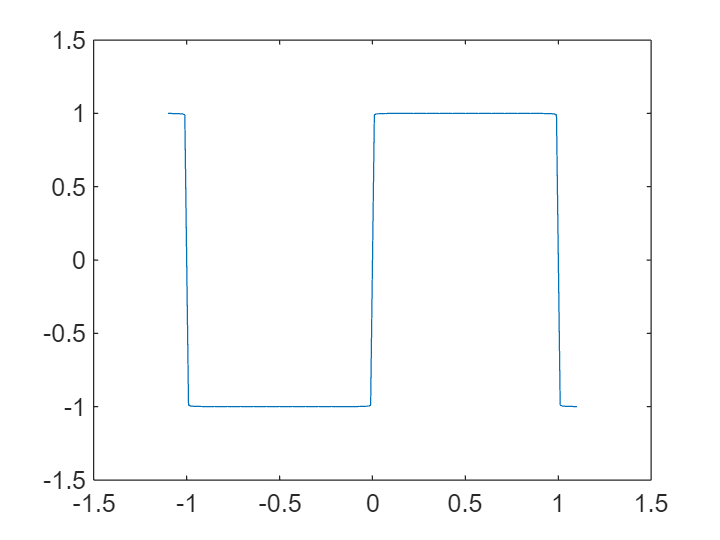

while true
Sum = Sum + n^2;
    if Sum > 1300
        Sum = Sum - n^2;
        n = n - 1;
        break;
    end

n = n + 1;
end
Sum 
n

4. Use the Taylor series:


$$\cos \;x=1-\frac{x^2 }{2!}+\frac{x^4 }{4!}-\frac{x^6 }{6!}+\ldotp \ldotp \ldotp$$


to write a program to compute $\cos \;x$ correct to four decimal places ($x$ is in radians). The program should determine how many terms are needed to obtain agreement with the function `cos` so that the error is less than 0.0001. Don’t take $x$ too large; that could cause rounding error.

**Answers:**

Sum = 0;
j = 0;
x = pi;
Sign = 1;
while true
    Sum = Sum + Sign * (x^j / factorial(j));
    Sign = -Sign
    j = j + 2
    if abs(Sum - cos(x)) < 0.0001
Sum

n = 15

        break;

Sum = 1240

    end

n = 15



end

5. A student borrows $10000 to buy a used car. Interest on her loan is compounded at the rate of 2% per month while the outstanding balance of the loan is more than $5000, and at 1% month otherwise. She pays back $300 every month, except for the last month, when the repayment must be less than $300. She pays at the end of the month, after the interest on the balance has been compounded. The first repayment is made one month after the loan is paid out. Write a program which displays a monthly statement of the balance (after the monthly payment has been made), the final payment, and the month of the final payment.

**Answers:**

6. A projectile is launched from the ground with an initial velocity of $60\;{\textrm{ms}}^{-1}$ at an angle of $50\degree$. Write a program which computes and displays the time in the air, and horizontal and vertical displacement from the launching point every 0.5 seconds, as long as the projectile remains above the ground. The following equations might be useful:


$$\begin{array}{l}
v_{0,x} =v_0 \;\cos \;\theta ,\\
v_{0,y} =v_0 \;\sin \;\theta ,
\end{array}$$
   
$$\begin{array}{l}
x=v_{0,x} t\\
y=y_0 +v_{0,y} t-\left({gt}^2 \right)/2
\end{array}$$


**Answers:**

x = [];
y = [];
t = 0;
i = 1;
v0 = 60;
g = 9.81;
theta = 50;
y0 = 0'
while true
    x(i) =  v0*cosd(theta)*t
    y(i) = y0 + v0*sind(theta)*t - (g*t^2)/2;
    if y(i) < 0
        break;
    end
    i = i + 1;

Sign = -1

j = 2

Sign = 1

j = 4

Sign = -1

j = 6

Sign = 1

j = 8

Sign = -1

j = 10

Sign = 1

j = 12

Sign = -1

j = 14

Sign = 1

j = 16

Sum = -1.0000

    t = t + 0.5;
end
t = 0 : 0.5 : t;
plot(x, y)

7. A prime number is a natural number (i.e., positive integer) larger than 1 that is indivisible by any other numbers except 1 and itself. This means that, when a prime number is divided by another smaller number, there is always a remainder. Compute and display all prime numbers not greater than 1000. Use the function `rem` to determine whether there is a remainder after division. Also, vectorize your code whenever possible. Do not simply use the function `isprime` to determine whether a number is a prime or not. 

**Answers:**

y0 = 0

x = 0

x =          0   19.2836


x =          0   19.2836   38.5673


x =          0   19.2836   38.5673   57.8509


x =          0   19.2836   38.5673   57.8509   77.1345


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199  231.4035


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199  231.4035  250.6872


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199  231.4035  250.6872  269.9708


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199  231.4035  250.6872  269.9708  289.2544


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199  231.4035  250.6872  269.9708  289.2544  308.5381


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199  231.4035  250.6872  269.9708  289.2544  308.5381  327.8217


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199  231.4035  250.6872  269.9708  289.2544  308.5381  327.8217  347.1053


x =          0   19.2836   38.5673   57.8509   77.1345   96.4181  115.7018  134.9854  154.2690  173.5527  192.8363  212.1199  231.4035  250.6872  269.9708  289.2544  308.5381  327.8217  347.1053  366.3889


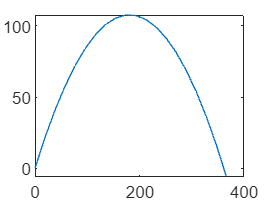

Num = 2

Num = 3

Num = 5

Num = 7

Num = 11

Num = 13

Num = 17

Num = 19

Num = 23

Num = 29

Num = 31

Num = 37

Num = 41

Num = 43

Num = 47

Num = 53

Num = 59

Num = 61

Num = 67

Num = 71

Num = 73

Num = 79

Num = 83

Num = 89

Num = 97

Num = 101

Num = 103

Num = 107

Num = 109

Num = 113

Num = 127

Num = 131

Num = 137

Num = 139

Num = 149

Num = 151

Num = 157

Num = 163

Num = 167

Num = 173

Num = 179

Num = 181

Num = 191

Num = 193

Num = 197

Num = 199

Num = 211

Num = 223

Num = 227

Num = 229

Num = 233

Num = 239

Num = 241

Num = 251

Num = 257

Num = 263

Num = 269

Num = 271

Num = 277

Num = 281

Num = 283

Num = 293

Num = 307

Num = 311

Num = 313

Num = 317

Num = 331

Num = 337

Num = 347

Num = 349

Num = 353

Num = 359

Num = 367

Num = 373

Num = 379

Num = 383

Num = 389

Num = 397

Num = 401

Num = 409

Num = 419

Num = 421

Num = 431

Num = 433

Num = 439

Num = 443

Num = 449

Num = 457

Num = 461

Num = 463

Num = 467

Num = 479

Num = 487

Num = 491

Num = 499

Num = 503

Num = 509

Num = 521

Num = 523

Num = 541

Num = 547

Num = 557

Num = 563

Num = 569

Num = 571

Num = 577

Num = 587

Num = 593

Num = 599

Num = 601

Num = 607

Num = 613

Num = 617

Num = 619

Num = 631

Num = 641

Num = 643

Num = 647

Num = 653

Num = 659

Num = 661

Num = 673

Num = 677

Num = 683

Num = 691

Num = 701

Num = 709

Num = 719

Num = 727

Num = 733

Num = 739

Num = 743

Num = 751

Num = 757

Num = 761

Num = 769

Num = 773

Num = 787

Num = 797

Num = 809

Num = 811

Num = 821

Num = 823

Num = 827

Num = 829

Num = 839

Num = 853

Num = 857

Num = 859

Num = 863

Num = 877

Num = 881

Num = 883

Num = 887

Num = 907

Num = 911

Num = 919

Num = 929

Num = 937

Num = 941

Num = 947

Num = 953

Num = 967

Num = 971

Num = 977

Num = 983

Num = 991

Num = 997

for Num = 2 : 1000
    IsRemaindersZero = all((rem(Num, 2:Num-1)));
    if IsRemaindersZero
        Num
    end
end

